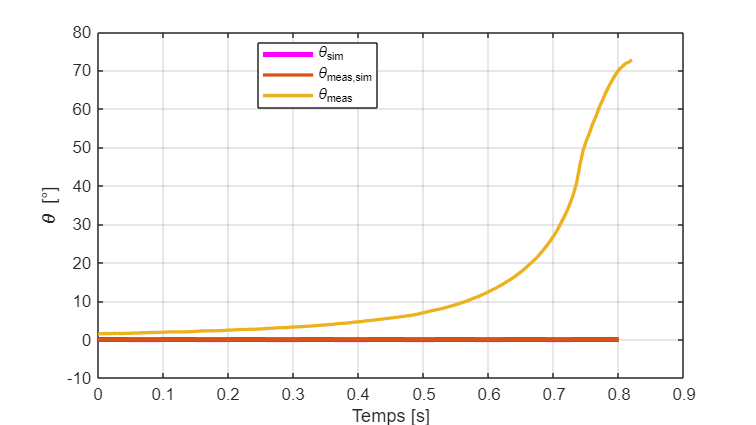

run("complete/complete_parameters.m")

% Free Fall (from .01°)
% Initial state
X0 = [0; 0; 0.03*pi/180; 0];


% Simulate

Tsim = .8;
t = 0:0.001:Tsim;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

theta_v = out.simout.signals.values(:,3);
theta_mes = out.theta_measure.signals.values();
t_v = out.tout;
% Read CSV
data = readmatrix('./data/free_fall_positive.csv');
tm_v= data(:,1);
tm_v = tm_v-tm_v(1); % Shifts at the start
thetam_v = data(:,5);


% theta
figure('Units','centimeters','Position',[2 2 16 9]);

hold on
plot(t_v, theta_v*180/pi, 'LineWidth', 3, 'Color', 'magenta', 'DisplayName', '\theta_{sim}');
plot(t_v, theta_mes, 'LineWidth', 2, 'DisplayName', '\theta_{meas,sim}');
plot(tm_v/1000, thetam_v, 'LineWidth', 2, 'DisplayName', '\theta_{meas}');

xlabel('Temps [s]');
ylabel('\theta [°]');
legend('Location','best');
grid on;
box on;
hold off;

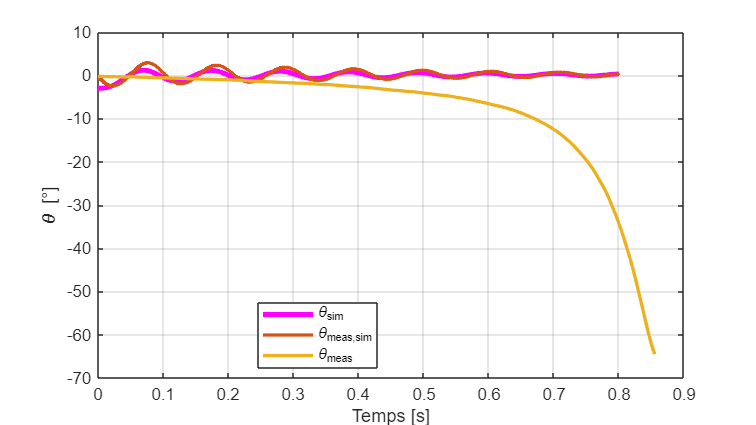

%exportgraphics(gca,'results/free_fall_positive.pdf','ContentType','vector');
% Simulate
X0 = [0; 0; -003*pi/180; 0];
Tsim = 0.8;
t = 0:0.001:Tsim;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

theta_v = out.simout.signals.values(:,3);
theta_mes = out.theta_measure.signals.values();
t_v = out.tout;
% Read CSV
data = readmatrix('./data/free_fall_negative.csv');
tm_v= data(:,1);
tm_v = tm_v-tm_v(1); % Shifts at the start
thetam_v = data(:,5);

% theta
figure('Units','centimeters','Position',[2 2 16 9]);

hold on
plot(t_v, theta_v*180/pi, 'LineWidth', 3, 'Color', 'magenta', 'DisplayName', '\theta_{sim}');
plot(t_v, theta_mes, 'LineWidth', 2, 'DisplayName', '\theta_{meas,sim}');
plot(tm_v/1000, thetam_v, 'LineWidth', 2, 'DisplayName', '\theta_{meas}');

xlabel('Temps [s]');
ylabel('\theta [°]');
legend('Location','best');
grid on;
box on;
hold off;

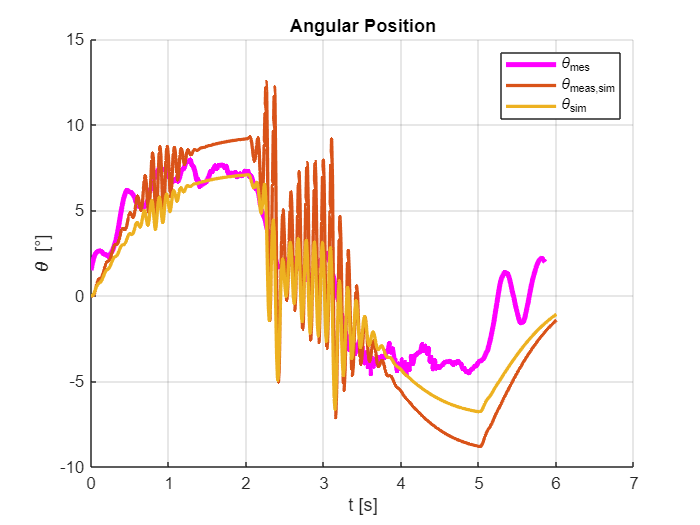

%exportgraphics(gca,'results/free_fall_negative.pdf','ContentType','vector');

% Trapezoidal (0,0.3,0) in 5s, 2.5s rise/fall
% Simulate
X0 = [0; 0; 0; 0];

% Trapezoidal/Triangular velocity reference
v_peak = 0.7;        % m/s
Tsim = 6;
t = 0:0.001:Tsim;

t_rise = 2;
t_fall = 2;
t_tot  = 5;

t_flat = t_tot - (t_rise + t_fall);

v_ref = zeros(size(t));

for i = 1:length(t)

    if t(i) < t_rise
        % Ramp up
        v_ref(i) = v_peak * t(i) / t_rise;

    elseif t(i) < (t_rise + t_flat)
        % Constant section
        v_ref(i) = v_peak;

    elseif t(i) < t_tot
        % Ramp down
        v_ref(i) = v_peak * (t_tot - t(i)) / t_fall;

    else
        % After profile ends
        v_ref(i) = 0;
    end

end

input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

theta_v = out.simout.signals.values(:,3);
theta_mes = out.theta_measure.signals.values();
x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
dtheta_v = out.simout.signals.values(:,4);
torque_v = out.torque.signals.values();
domega = out.domega.signals.values();
ddx = out.ddx.signals.values(1,:);
theta_target = out.theta_target.signals.values();
t_v = out.tout;


data = readmatrix('./data/trapezoidal_move_pos_2.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;
thetam_v = data(:,6);
theta_targetm_v = data(:,5);


xm_v = xm_v - xm_v(1); % Shifts to 0
tm_v = tm_v-tm_v(1); % Shifts to 0

% theta
figure;
hold on;
plot(tm_v, thetam_v, "LineWidth", 3,"Color","magenta","DisplayName","\theta_{mes}");
plot(t_v, theta_mes, 'LineWidth', 2,"DisplayName","\theta_{meas,sim}");
plot(t_v, theta_v*180/pi, 'LineWidth', 2,"DisplayName","\theta_{sim}");

xlabel('t [s]');
ylabel('\theta [°]');
title('Angular Position');
legend('show');
grid on;
hold off;
exportgraphics(gca,'results/trapez_move_theta.pdf','ContentType','vector');

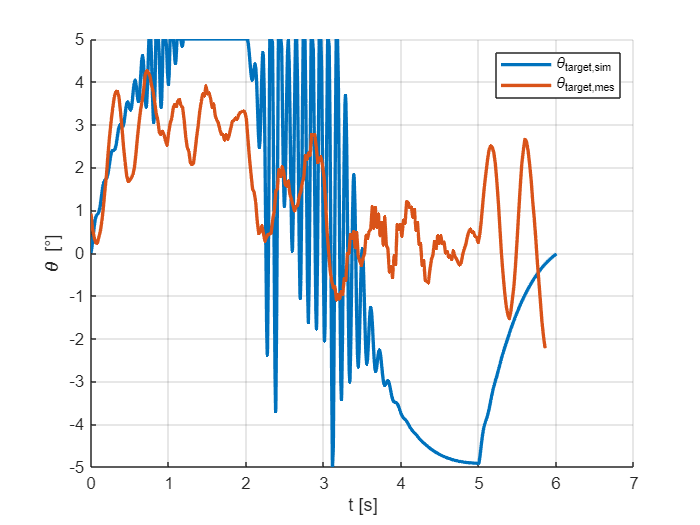





figure;
hold on;
plot(t_v, theta_target, 'LineWidth', 2,"DisplayName","\theta_{target,sim}");
plot(tm_v, theta_targetm_v, 'LineWidth', 2,"DisplayName","\theta_{target,mes}");
xlabel('t [s]');
ylabel('\theta [°]');
title(' ');
legend("show");
grid on;
hold off;

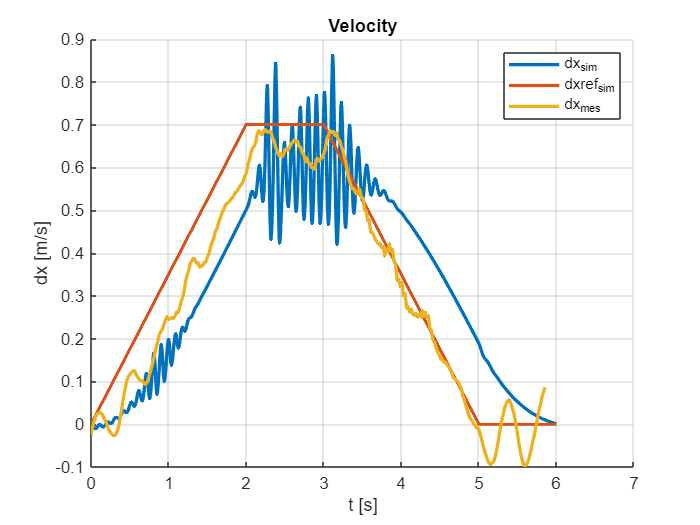


figure;
hold on;
plot(t_v, dx_v, "LineWidth", 2,"DisplayName","dx_{sim}");
plot(t, v_ref, "LineWidth", 2,"DisplayName","dxref_{sim}");
plot(tm_v,dxm_v, "LineWidth",2,"DisplayName","dx_{mes}");
xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/trapez_move_velocity.pdf','ContentType','vector');

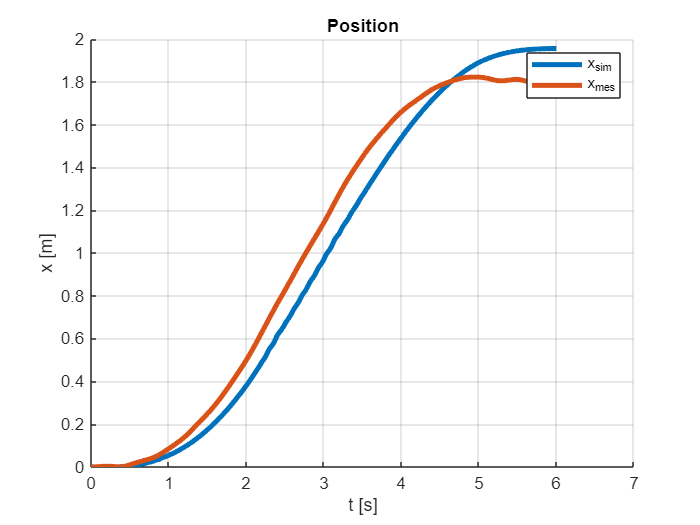




figure;
hold on;
plot(t_v, x_v, "LineWidth", 3,"DisplayName","x_{sim}");
plot(tm_v,xm_v, "LineWidth",3,"DisplayName","x_{mes}");
xlabel('t [s]');
ylabel('x [m]');
title('Position');
legend('show');

grid on;
hold off;

exportgraphics(gca,'results/trapez_move_position.pdf','ContentType','vector');

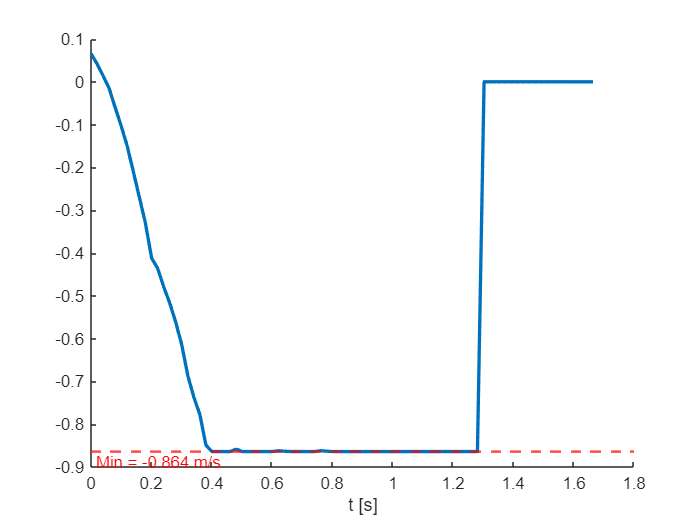

% MAX SPEED
data = readmatrix('./data/max_speed_max_angle.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;
thetam_v = data(:,6);
theta_targetm_v = data(:,5);


figure;
hold on;

plot(tm_v, dxm_v, "LineWidth", 2, "DisplayName", "dx_{mes}");

% Minimum value
min_dx = min(dxm_v);

% Horizontal line at the minimum
yline(min_dx, '--r', ...
    sprintf('Min = %.3f m/s', min_dx), ...
    'LineWidth', 1.5, ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom');

xlabel('t [s]');

ylabel('dx [m/s]','limit');

Error using xyzlabel (line 4)
Incorrect number of inputs for property-value pairs.

Error in ylabel (line 7)
    xyzlabel("YLabel", varargin);

title('Max Velocity');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/max_speed.pdf','ContentType','vector');
% MAX ANGLE
figure;
hold on;

plot(tm_v, thetam_v, "LineWidth", 3, "Color", "magenta", "DisplayName", "\theta_{mes}");
plot(tm_v, dxm_v, "LineWidth", 2, "DisplayName", "dx_{mes}");

% Find the first crossing of -30°
idx = find(thetam_v <= -30, 1, 'first');

% Interpolate for a more accurate crossing time
t_cross = interp1(thetam_v(idx-1:idx), tm_v(idx-1:idx), -30);

% Vertical line at the crossing
xline(t_cross, '--k', ...
    sprintf('t = %.2f s', t_cross), ...
    'LineWidth', 1.5, ...
    'LabelVerticalAlignment', 'middle',"DisplayName","\theta_{lim}");

% Horizontal line at -30°
yline(-30, '--k', '-30°', ...
    'LineWidth', 1.5, ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom',"DisplayName","\theta_{lim}");
plot(t_cross, -30, 'ko', ...
    'MarkerFaceColor', 'k', ...
    'DisplayName', '-30° crossing');
xlabel('t [s]');
ylabel('\theta [°]');
title('Angular Position');
legend('show', 'Location', 'best');
grid on;
hold off;

exportgraphics(gca, 'results/max_angle.pdf', 'ContentType', 'vector');
% POS RESPONSE
data = readmatrix('./data/hold_pos.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;
thetam_v = data(:,6);
theta_targetm_v = data(:,5);

figure;
hold on;
plot(tm_v,dxm_v, "LineWidth",2,"DisplayName","dx_{mes}");
plot(tm_v,dx_targetm_v, "LineWidth",2,"DisplayName","dx_{target,mes}");

xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/hold_positive_speed.pdf','ContentType','vector');
figure;
hold on;
plot(tm_v, thetam_v, 'LineWidth', 2,"DisplayName","\theta_{mes}");
plot(tm_v, theta_targetm_v, 'LineWidth', 2,"DisplayName","\theta_{target,mes}");
xlabel('t [s]');
ylabel('\theta [°]');
title('Angle');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/hold_positive_angle.pdf','ContentType','vector');
% POS RESPONSE
data = readmatrix('./data/hold_neg.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;
thetam_v = data(:,6);
theta_targetm_v = data(:,5);

figure;
hold on;
plot(tm_v,dxm_v, "LineWidth",2,"DisplayName","dx_{mes}");
plot(tm_v,dx_targetm_v, "LineWidth",2,"DisplayName","dx_{target,mes}");

xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/hold_negative_speed.pdf','ContentType','vector');
figure;
hold on;
plot(tm_v, thetam_v, 'LineWidth', 2,"DisplayName","\theta_{mes}");
plot(tm_v, theta_targetm_v, 'LineWidth', 2,"DisplayName","\theta_{target,mes}");
xlabel('t [s]');
ylabel('\theta [°]');
title('Angle');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/hold_negative_angle.pdf','ContentType','vector');
% POS IMPULSE RESPONSE
data = readmatrix('./data/pulse_positive.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;
thetam_v = data(:,6);
theta_targetm_v = data(:,5);

figure;
hold on;
plot(tm_v, thetam_v, 'LineWidth', 2,"DisplayName","\theta_{mes}");
xlabel('t [s]');
ylabel('\theta [°]');
title('Angle');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/pulse_positive.pdf','ContentType','vector');
% POS IMPULSE RESPONSE
data = readmatrix('./data/pulse_negative.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;
thetam_v = data(:,6);
theta_targetm_v = data(:,5);

figure;
hold on;
plot(tm_v, thetam_v, 'LineWidth', 2,"DisplayName","\theta_{mes}");
xlabel('t [s]');
ylabel('\theta [°]');
title('Angle');
legend("show");
grid on;
hold off;

exportgraphics(gca,'results/pulse_negative.pdf','ContentType','vector');